## 画图1，通常导出设置为固定字号8榜-Arial-加粗-线宽1.2榜，加载后应用于图窗，下图为粗略估计，实际上直接在图窗中，点击小鼠标==>属性检查器==>输入posi==>抄坐标

## 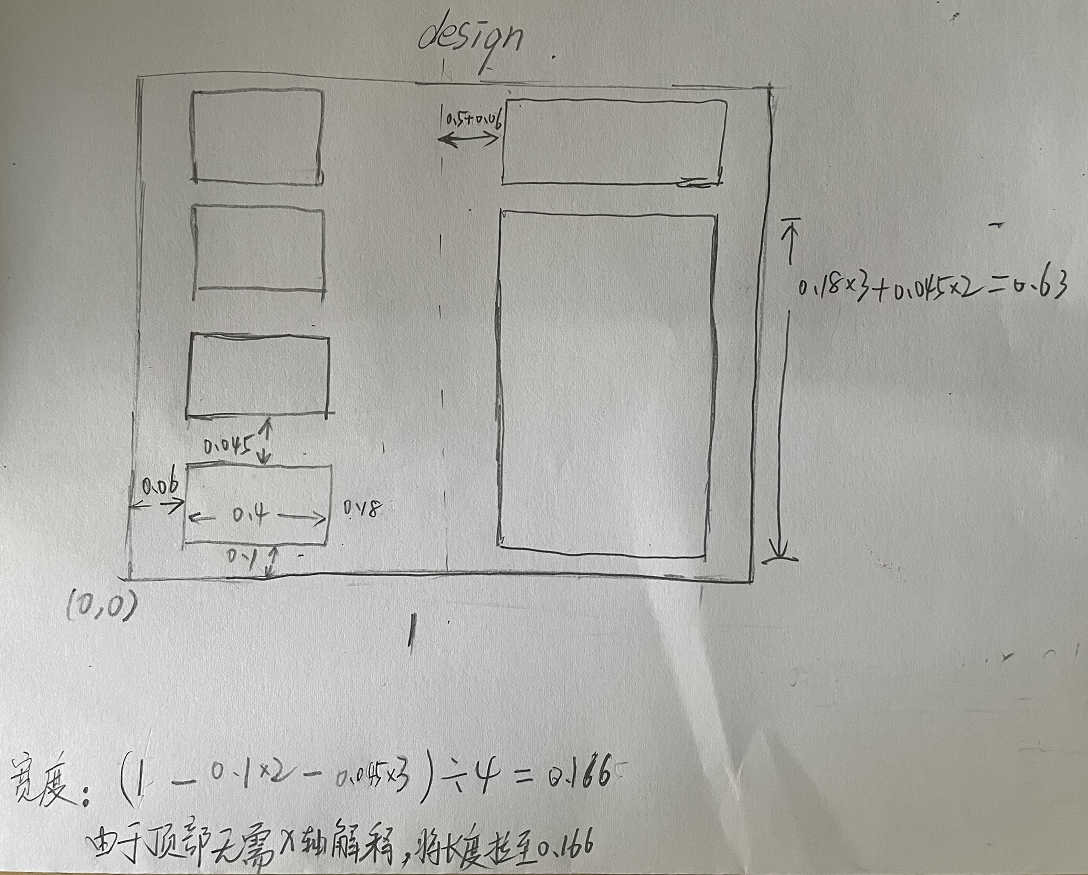

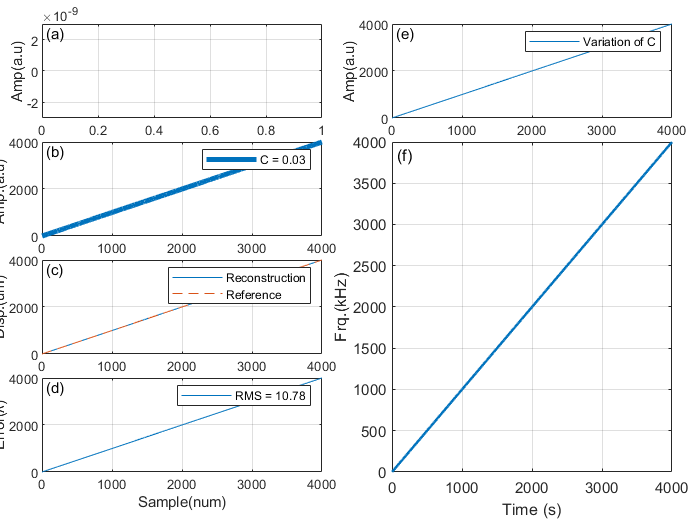

clc;
clear all;
close all;
figure(1); N = 4000;
% 第1幅图
axes('Position',[0.06 0.775 0.4 0.18]);  axis tight;  % 设置图像位置 + 坐标紧凑型 
plot((1:N), (1:N)); grid on;  % 作图 + 网格
ylabel('Amp(a.u)'); title('(a)', 'Units', 'normalized', 'Position', [0.045 0.8]);  % y轴注释 + 左上角角标，小标位置是相对当前图而言
set(gca, 'YLim', [-3*10^-9, 3*10^-9]);  % 设置y轴的范围

% 第2幅图
axes('Position',[0.06 0.55 0.4 0.18]);  axis tight; 
plot((1:N), (1:N), 'Linewidth', 3); grid on;
ylabel('Amp.(a.u) '); title('(b)', 'Units', 'normalized', 'Position', [0.045 0.8]); legend("C = 0.03");

% 第3幅图
axes('Position',[0.06 0.325 0.4 0.18]);  axis tight;
plot((1:N), (1:N)); grid on;
hold on;
plot((1:N), (1:N), "LineStyle","--"); grid on;
ylabel('Disp.(um)'); title('(c)', 'Units', 'normalized', 'Position', [0.045 0.8]); legend("Reconstruction","Reference");

% 第4幅图
axes('Position',[0.06 0.1 0.4 0.18]);  axis tight; 
plot((1:N), (1:N)); grid on;
ylabel('Amp(a.u) '); title('(d)', 'Units', 'normalized', 'Position', [0.045 0.8]); xlabel('Sample(num)'); ylabel('Error(λ)');legend("RMS = 10.78"); 

% 第5幅图
axes('Position',[0.56 0.775 0.4 0.18]);  axis tight; 
plot((1:N), (1:N)); grid on;
ylabel('Amp(a.u)'); title('(e)', 'Units', 'normalized', 'Position', [0.045 0.8]); legend('Variation of C') 

% 第6幅图
axes('Position',[0.56 0.1 0.4 0.63]);  axis tight;  
plot((1:N), (1:N), 'Linewidth', 1.5); grid on;
title('(f)', 'Units', 'normalized', 'Position', [0.045 0.93]); xlabel('Time (s)');ylabel('Frq.(kHz)');   % y轴注释 + 左上角角标

set(gcf, 'color', 'w');
